Returns the virtual array for transmit beamforming (TXBF) from the convolution of the receive and transmit array elements laying in the horizontal plane. Forms the steering vector for the virtual array using only a set of the non-overlapping virtual elements.

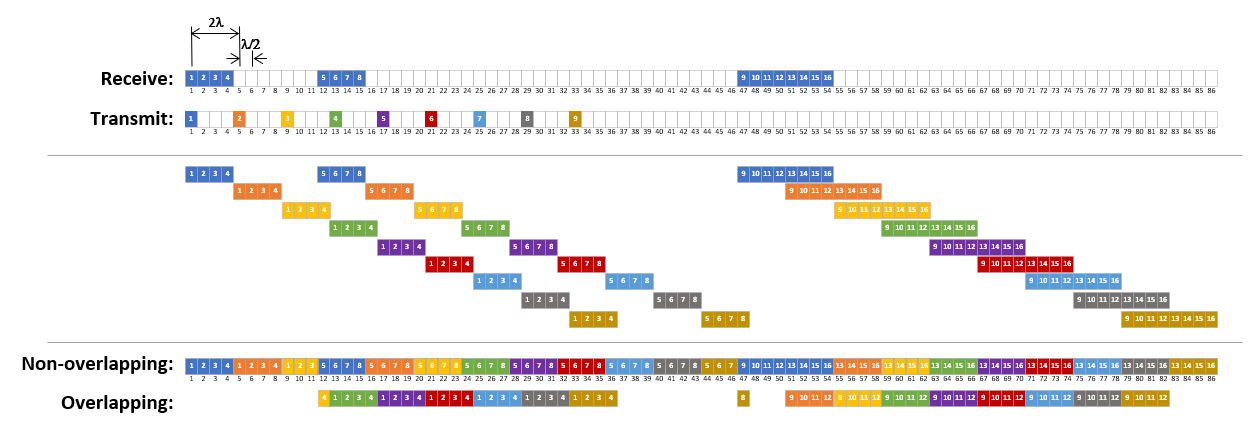

function vxSteer = helperVirtualSteeringVector(txSteer,rxSteer)
% This function is for demo purposes only and may be removed in the future

%#codegen
%   Copyright 2021-2022 The MathWorks, Inc.

% Returns the steering vector with non-overlapping elements for the virtual
% array. When multiple virtual elements overlap, only one of them is used.
vxSteer = [ ...
    bsxfun(@times,txSteer(1,:),rxSteer(1:4,:)); ...
    bsxfun(@times,txSteer(2,:),rxSteer(1:4,:)); ...
    bsxfun(@times,txSteer(3,:),rxSteer(1:3,:)); ...
    bsxfun(@times,txSteer(1,:),rxSteer(5:8,:)); ...
    bsxfun(@times,txSteer(2,:),rxSteer(5:8,:)); ...
    bsxfun(@times,txSteer(3,:),rxSteer(5:8,:)); ...
    bsxfun(@times,txSteer(4,:),rxSteer(5:8,:)); ...
    bsxfun(@times,txSteer(5,:),rxSteer(5:8,:)); ...
    bsxfun(@times,txSteer(6,:),rxSteer(5:8,:)); ...
    bsxfun(@times,txSteer(7,:),rxSteer(5:8,:)); ...
    bsxfun(@times,txSteer(8,:),rxSteer(5:8,:)); ...
    bsxfun(@times,txSteer(9,:),rxSteer(5:7,:)); ...
    bsxfun(@times,txSteer(1,:),rxSteer(9:16,:)); ...
    bsxfun(@times,txSteer(2,:),rxSteer(13:16,:)); ...
    bsxfun(@times,txSteer(3,:),rxSteer(13:16,:)); ...
    bsxfun(@times,txSteer(4,:),rxSteer(13:16,:)); ...
    bsxfun(@times,txSteer(5,:),rxSteer(13:16,:)); ...
    bsxfun(@times,txSteer(6,:),rxSteer(13:16,:)); ...
    bsxfun(@times,txSteer(7,:),rxSteer(13:16,:)); ...
    bsxfun(@times,txSteer(8,:),rxSteer(13:16,:)); ...
    bsxfun(@times,txSteer(9,:),rxSteer(13:16,:)); ...
    ];
end